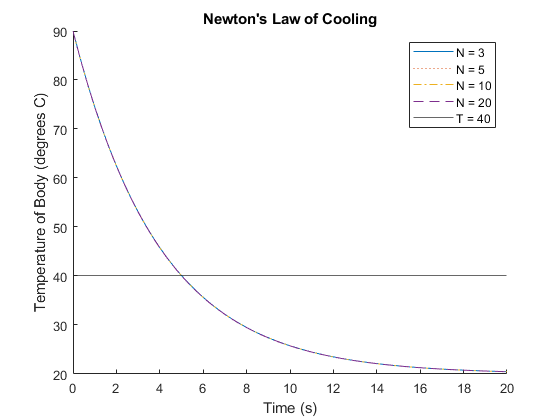

clear
clc
%Initialize N vec
N = [3, 5, 10, 20];
figure
hold on
%get sol, plot
for n = N
    [temp, t] = IEMsolver(n);
    if n == 3
        plot(t, temp, "-")
    elseif n == 5
        plot(t, temp, ":")
    elseif n == 10
        plot(t, temp, "-.")
    elseif n == 20
        plot(t, temp, "--")
    end
end
%aesthetics
title("Newton's Law of Cooling")
xlabel("Time (s)")
ylabel("Temperature of Body (degrees C)")
%line at 40 to get time to T = 40
yline(40)
legend("N = 3", "N = 5", "N = 10", "N = 20", "T = 40")

function [temp, t] = IEMsolver(n)
    %initialize constants
    T_0 = 90;
    T_a = 20;
    k = 0.25;
    %setup delta_t and t
    delta_t = 20/n;
    t = 0:delta_t:20;
    %initialize solution
    sol = NaN(1, length(t));
    sol(1) = T_0;
    %IEM Solving
    for m = 2 : length(t)
        sol(m) = sol(m - 1) + delta_t*((-k*(sol(m - 1) - T_a)));
        sol(m) = sol(m - 1) + (delta_t/2)*((-k*((sol(m - 1) - T_a))) + ((-k*((sol(m) - T_a)))));
    end
    temp = sol;
end

Recommended Time Steps: N = 10

T needed to reach 40C ~ 5.011s